**Plot the raw EEG signal and inspect the signal quality over time. Zoom in on the signal,**

**find the artifacts, and learn to distinguish noisy signals from good quality data. You don’t**

**need to submit this part, but it is very important to be able to recognize artifacts if you**

**wish to work with EEG signals going forward.**

Load raw EEG data.

data = load('Lab3_Group2_Raw.mat');   % contains variable 'y'

%time is the first row we get, then: Cz,P3,Pz,P4,Oz
t   = data.y(1,:);        % time going to be in seconds
EEG = data.y(2:end,:);    %5 x N EEG

% sampling rate from our vector. 
fs = 1/mean(diff(t));
size(EEG), fs

ans =            5       90377


fs = 256

Extract the EEG data

channel_names = {'Cz','P3','Pz','P4','Oz'};

% show some basic information
disp(['Channels x Samples: ', mat2str(size(EEG))]);

Channels x Samples: [5 90377]


disp(['Sampling rate in Hz: ', num2str(fs)]);

Sampling rate in Hz: 256


Plot raw EEG signals

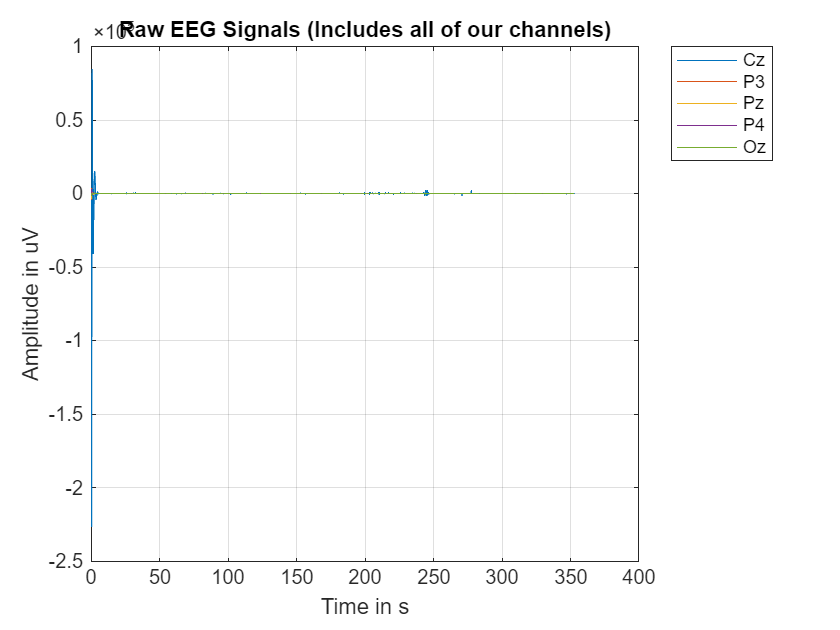

figure;
plot(t, EEG'); grid on;
xlabel('Time in s');
ylabel('Amplitude in uV');
title('Raw EEG Signals (Includes all of our channels)');
legend(channel_names, 'Location','bestoutside');

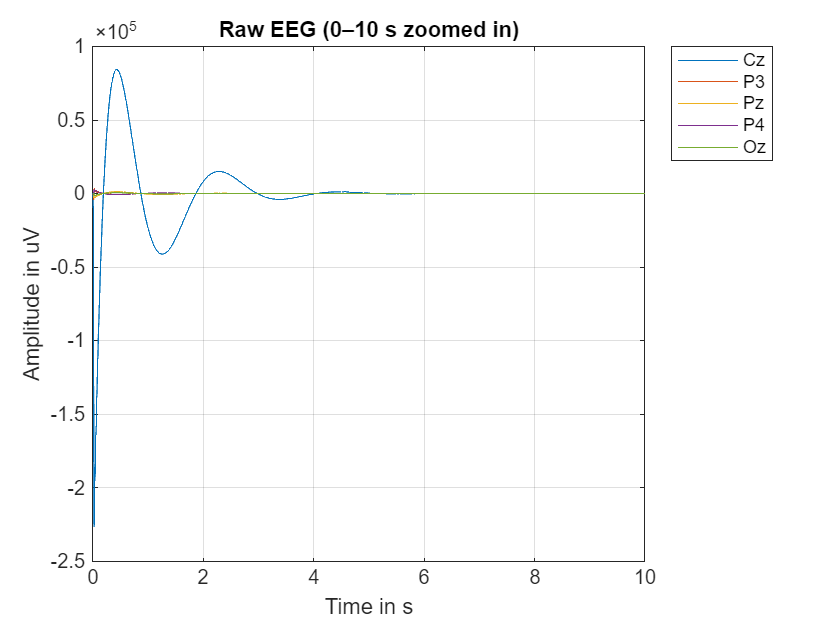

%this cell is meant for the zoomed in view for the homework question
figure;
plot(t, EEG'); grid on;
xlim([t(1) t(1)+10]);
xlabel('Time in s'); ylabel('Amplitude in uV');
title('Raw EEG (0–10 s zoomed in)');
legend(channel_names, 'Location','bestoutside');

Investigating the abnormally large spike at the beginning of the recording (same as last HW)


%% checking the min and max values for each channel, isolating which are problematic

max_vals  = max(EEG, [], 2);
min_vals  = min(EEG, [], 2);

for ch = 1:numel(channel_names)
    fprintf('%s: Max = %.2f uV, Min = %.2f uV\n', ...
        channel_names{ch}, max_vals(ch), min_vals(ch));
end

Cz: Max = 84323.16 uV, Min = -226821.16 uV
P3: Max = 3429.82 uV, Min = -4100.83 uV
Pz: Max = 1205.13 uV, Min = -3261.76 uV
P4: Max = 2630.57 uV, Min = -827.66 uV
Oz: Max = 538.87 uV, Min = -1692.81 uV


%trying to find that one bad delection in the beginning of the recording. 
overall_max = max(abs(EEG(:)));
fprintf('Overall largest absolute amplitude: %.2f uV\n', overall_max);

Overall largest absolute amplitude: 226821.16 uV


Inital aritfact correction (detrending and winsorizing)% Detrend (remove per-channel mean)

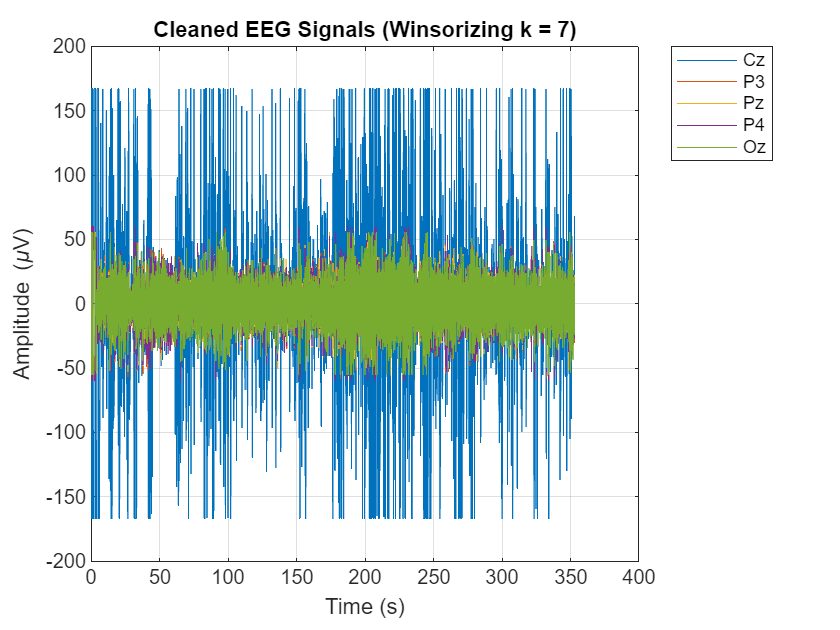

%same as last hw
EEG_detrended = EEG - mean(EEG, 2);

% Winsorizing same as last homework as well. 
k = 7; %alter, lower = harsher threshold. 

EEG_clean = EEG_detrended;
for ch = 1:size(EEG_clean,1)
    m    = median(EEG_detrended(ch,:));
    madv = median(abs(EEG_detrended(ch,:) - m)) + eps;
    lower = m - k*madv;  upper = m + k*madv;
    EEG_clean(ch,:) = min(max(EEG_detrended(ch,:), lower), upper);
end

% Plot cleaned signals
figure;
plot(t, EEG_clean'); grid on;
xlabel('Time (s)'); ylabel('Amplitude (\muV)');
title(sprintf('Cleaned EEG Signals (Winsorizing k = %d)', k));
legend(channel_names, 'Location','bestoutside');

When we first started examining this raw EEG recording, the most striking feature was definitely the enormous spike that you can observe at the very beginning of the session, where you can see that the electrode Cz is reaching values of above ±200,000 µV. This kind of amplitude is several orders of magnitude higher than anything you might see in a genuine EEG, meaning that such an extreme artifact has almost certainly been introduced by some contamination: amplifier startup, cable motion, or electrode settling. If we left it uncorrected of the rest of the homework, this single event would go on to dominate the downstream analyses, rendering any subsequent power estimates or envelope extraction meaningless.

Even beyond this initial artifact, when I looked into the raw statistics (since I had doubts regarding the quality of the signal), they revealed unreasonably large values across all of the channels. I would think that these values would be consistent with what we would expect from movement contamination, muscle activity, or maybe simply poor electrode contact rather than any sort of viable neural activity. Because these distortions are not isolated to one channel, they cannot be ignored by simply dropping a bad electrode; instead, they require preprocessing.

Since these distortions not isolated to one channel, I decided to implement some further processing. First, I decided (like the first homework) to implement detrending, which was applied first to remove any of the channel-wise DC offsets we might be seeing. Then, as I had done in the previous homework, winsorizing was used to reduce the influence of these extreme outliers (like the particularly large artifact in the start of the recording) by clipping the values that happen to lay far beyond the typical amplitude distribution (which is defined relative to the median and the median absolute deviation). It is my hope that this strategy manages to preserve most of the continuous EEG fluctuations while simultaneously limiting the effect of the aforementioned sudden spikes.

After the detrending and winsorizing, it looks as if the overall amplitude scale was nearly reduced to the expected range (as shown in the cleaned EEG signal plot). However, it seems clear to me that many of the channels still contain some sort of residual noise 

However, it seems clear to me that some residual noise remains evident across these channels, which is most evident in Cz. Even with the winsorizing that I previously mentioned, Cz continues to show clipped amplitudes at the imposed thresholds, which would suggest that there are persistent artifacts introduced by some sort of electrode movement or muscle activity. I believe that this demonstrates we cannot fully eliminate the noise sources inherent to the recording done in the lab. 

**Generate an envelope detection function in MATLAB. The function should use the**

**following format:**

`function [envelope]=` `envelope_detection(raw_EEG_signal, band_low_cut_off,`

`band_high_cut_off,` `low_cut_off)`

**in which**, `band_low_cut_off` **and** `band_high_cut_off` **are low cut off and high cut off**

**frequencies of bandpass filter respectively and, **`low_cut_off `**is cut off frequency of the**

**lowpass filter in the model.**

**You are free to use any toolbox or function you want, or you may replicate the functions**

**you used in Simulink.**

% this is the envelope function
function [envelope] = envelope_detection(raw_EEG_signal, band_low_cut_off, band_high_cut_off, low_cut_off)
    fs = 256;

    %\want to make sure that we have channels x samples
    if size(raw_EEG_signal,1) > size(raw_EEG_signal,2)
        raw_EEG_signal = raw_EEG_signal'; % force rows = samples
    end

    % 0 phase bandpass filter 
    [b_band, a_band] = butter(4, [band_low_cut_off band_high_cut_off]/(fs/2), 'bandpass');
    bandpassed = filtfilt(b_band, a_band, double(raw_EEG_signal)')';  % again lets make sure that we have channels x samples

    % 2) here is the recitify to emulate what we did in the lab recording
    rectified = abs(bandpassed);

    % 3) same thing as the lab, taking the mean across channels. 
    mean_rectified = mean(rectified, 1);

    % 4) low pass filter at the end for the averaged input. 
    [b_lp, a_lp] = butter(4, low_cut_off/(fs/2), 'low');
    envelope = filtfilt(b_lp, a_lp, mean_rectified);
end



**Plot the output of your function and the output of the Simulink model (recorded in the**

**lab) on the same figure using different colors. Choose a time window that ensures that the**

**signal is clearly observable. Include two figures:**

**1. One figure illustrating a stretch of time where the two outputs are very similar**

**2. One figure for a period where the outputs are different**

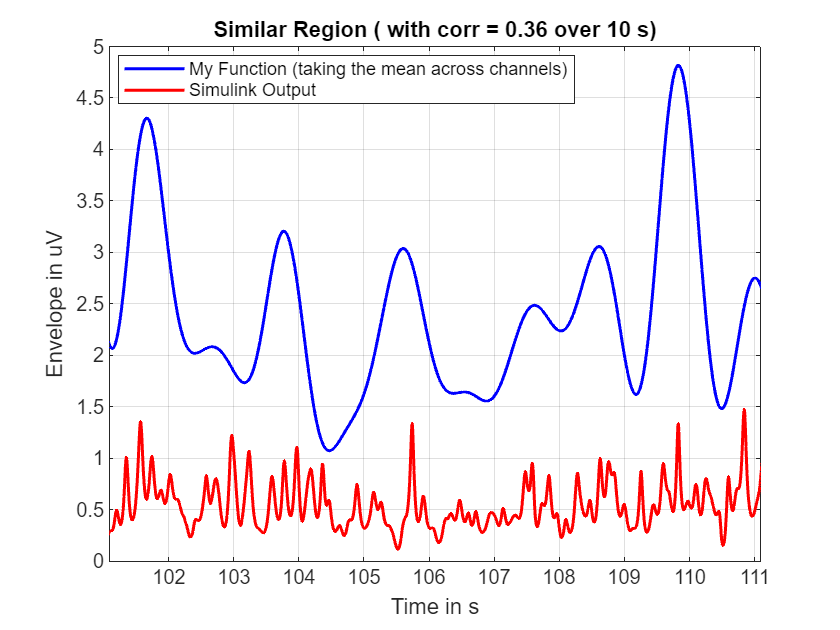

%compare with the simulink bnlocks we used in the lab

%load the data
env_data = load('Lab3_Group2_Envelope.mat');
t_sim   = env_data.y(1,:); %no more time
sim_env = env_data.y(2,:);

%compute the envelope on each each of the cleaned channels, then take the mean across channels (match Simulink Mean block) ---
band_low = 8; band_high = 12; lp = 1;  % Alpha wave freq. and 1 Hz LPF from the experiments we ran
my_env_all = zeros(size(EEG_clean));
for ch = 1:size(EEG_clean,1)
    my_env_all(ch,:) = envelope_detection(EEG_clean(ch,:), band_low, band_high, lp);
end
my_env_mean = mean(my_env_all, 1);

%just make sure that the time is aligned 
if ~isequal(t, t_sim)
    my_env_mean = interp1(t, my_env_mean, t_sim, 'linear', 'extrap');
    t = t_sim;
end

% tricky pick the auto 10 s windows pick the one with highest correlation,
% and then the one with the lowest corr after --> display
win_sec = 10;
L = max(1, round(win_sec * fs));
L = min(L, numel(t));  % clamp for safety. 

scores = zeros(1, numel(t)-L+1);
for i = 1:(numel(t)-L+1)
    a = my_env_mean(i:i+L-1);
    b = sim_env(i:i+L-1);

    % z-score both
    a = a - mean(a);  sa = std(a);
    b = b - mean(b);  sb = std(b);

    if sa == 0 || sb == 0
        scores(i) = 0;               % no divide by zero
    else
        scores(i) = (a * b') / ((L-1) * sa * sb);   %  r
    end
end

[best_corr,  i_best]  = max(scores);
[worst_corr, i_worst] = min(scores);

%the plot for the similar region:
figure;
plot(t, my_env_mean, 'b', 'LineWidth', 1.5); hold on;
plot(t, sim_env,     'r', 'LineWidth', 1.5); grid on;
xlim([t(i_best) t(min(i_best+L-1, numel(t)))]);
xlabel('Time in s'); ylabel('Envelope in uV');
legend('My Function (taking the mean across channels)', 'Simulink Output', 'Location','best');
title(sprintf('Similar Region ( with corr = %.2f over %g s)', best_corr, win_sec));

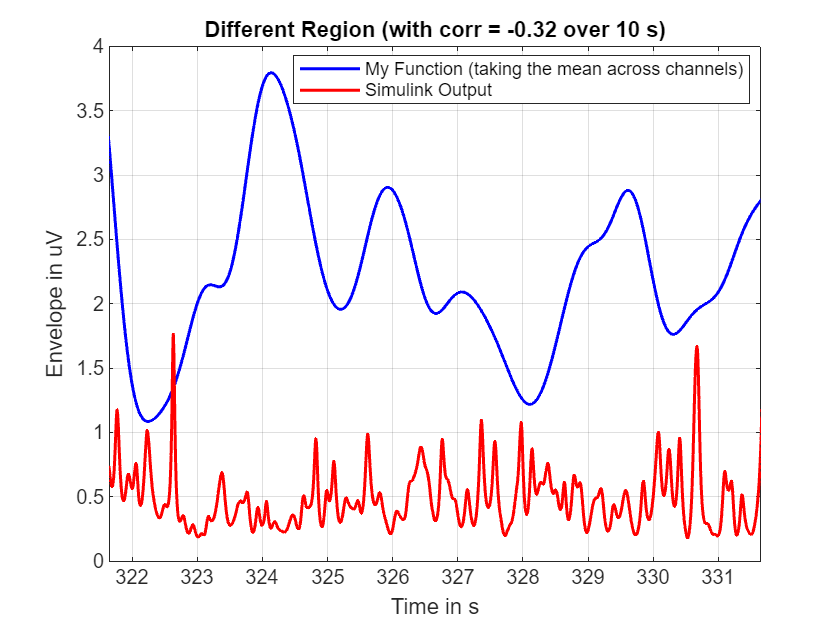

%One figure for a period where the outputs are different

figure;
plot(t, my_env_mean, 'b', 'LineWidth', 1.5); hold on;
plot(t, sim_env,     'r', 'LineWidth', 1.5); grid on;
xlim([t(i_worst) t(min(i_worst+L-1, numel(t)))]);
xlabel('Time in s'); ylabel('Envelope in uV');
legend('My Function (taking the mean across channels)', 'Simulink Output', 'Location','best');
title(sprintf('Different Region (with corr = %.2f over %g s)', worst_corr, win_sec));

In the code cell where I implemented the function mentioned in question 2 of the homework, we take the raw EEG channels as input, apply a 4th-order Butterworth bandpass filter in the alpha wave frequency range, and then (to more accurately represent the simulink envelope) I rectified the result by taking the absolute value, then we averaged the rectified signal across all of the channels in order to approximate the Simulink *Mean* block that we used during our lab. Finally, I applied a low-pass filter to smooth said envelope. Importantly, I used filtfilt in MATLAB for the purpose of removing any sort of phase delay and spitting out a zero-phase output, which seems to be a common choice from what I hear.

In the last question, I compared the envelope that was generated from our previously mentioned MATLAB function against the Simulink output that we recorded during my group's lab time. I then loaded said Simulink file, computed our own envelope from our now cleaned and winsorized EEG data, and aligned these two signals in the time domain. To make the comparison more objective, I thought it best that both conditions made use of a sliding 10-second window that would compute the correlation scores between the two envelopes, going on to automatically select one segment with high correlation (One figure illustrating a stretch of time where the two outputs are very similar”) and one with low correlation (“One figure for a period where the outputs are different”) for plotting. 

From the graphs that were generated, the main observation that jumps out is that the Simulink output (pictured in red) is consistently lower in amplitude than the MATLAB output (in blue). I thought a lot about this, and I came up with a couple of theories as to why. The first theory is that this has to do with filter implementation. Basically, Simulink used IIR, a sort of real-time filter that works to naturally shrink and smooth our signal, while the MATLAB code used a method that removes lag and then attempts to keep the full size of the peaks. The second theory is that this could be due to input differences. Since my function was applied to detrended and winsorized (clean) EEG data, I believe that it would make sense for the Simulink pipeline that operated directly on the raw data to have consistently lower values. Together, maybe these factors can help explain why the MATLAB envelope tends to ride higher, while the Simulink trace that we obtained in the lab do sort of highlight the same general trends in the alpha activity. (corr = 0.36 over 10s) 